# Optimization of the single feeding trajectory

**Manipulated variables**

- `u = Q_in [L/h]`: feed rate

**Measured disturbance**

- `none`

**State variables**

- `x1 = V [L]`: liquid volume in the reactor

- `x2 = Xv [cell/L]`: viable cell density

- `x3 = Xt [cell/L]`: total cell density 

- `x4 = Gl`c` [mM]`: Glucose concentration

- `x5 = Gln [mM]`: Glutamine concentration

- `x6 = Lac [mM]`: Lactate concentration

- `x7 = Amm [mM]`: Ammonia concentration

- `x8 = mAb_ext [mg/L]`: extracellular mAb concentration

**Output variables: the same as the state variables**

**The goal:** to maximize the final mAb mass (`x1(Tf)*x8(Tf)`). 

**Contraints:** 

- Upper bound on the liquid volume (x`1`) 

## Specify the initial states.

V0 = 0.8;       % [L]
Xv0 = 2E+8;     % [cell]
Xt0 = 2E+8;     % [cell]
Glc0 = 25;      % [mM]
Gln0 = 4;       % [mM]
Lac0 = 0;       % [mM]
Amm0 = 0;       % [mM]
mAb_ext0 = 0;   % [mg/L] must be positive!

x0 = [V0; Xv0; Xt0; Glc0; Gln0; Lac0; Amm0; mAb_ext0];

Specify the nominal inputs.

u0 = 0;

## Design nonlinear MPC with the true model

Create a nonlinear MPC object with 16 states, 16 outputs, 1 manipulated variables, and NO measured disturbance.

nlmpcTrue = nlmpc(8,8,1); % nlpmc object

標準のコスト関数では、MV が OV より少ないため、既定で 1 つ以上の OV に 0 の重みが割り当てられます。


Given the expected batch duration `Tf`, choose the controller sample time `Ts` and prediction horizon.

Tf = 240;   % [h] process duration
Ts = 12;    % [h] prediction model sample time
N = Tf/Ts;  % [step] prediction horizon
nlmpcTrue.Ts = Ts;
nlmpcTrue.PredictionHorizon = N;
% nlmpcobj.ControlHorizon = N;
nlmpcTrue.ControlHorizon = (48/Ts)*ones(5,1);
nlmpcTrue.Optimization.MVInterpolationOrder = 1;

### Specify the nonlinear state function in the controller

The function `fedbatch_StateFcnDT` converts the continuous-time model to discrete time using a multi-step Forward Euler integration formula.

STATEFCN = @deTremblay1992StateFcn;
nlmpcTrue.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcTrue.Model.OutputFcn = @(x,u) x;

% the nonlinear state function is for discrete-time models.
nlmpcTrue.Model.IsContinuousTime = false;

### Specify the bounds for input/output variables

Specify the bounds for a manipurated input variable (feed rate`)`.

% states
stateName = {'V','Xv','Xt','Glc','Gln','Lac','Amm','mAb_ext'};
stateUnit = {'L', 'cell/L', 'cell/L', 'mM', 'mM', 'mM', 'mM', 'mg/L'};
stateScaleFactor = [1.2 1.5E+9 1.5E+9 25 4 30 3 150];

for stateIdx = 1:8
    nlmpcTrue.States(stateIdx).Name = stateName{stateIdx};
    nlmpcTrue.States(stateIdx).ScaleFactor = stateScaleFactor(stateIdx);
    nlmpcTrue.States(stateIdx).Units = stateUnit{stateIdx};
    % nlmpcTrue.States(stateIdx).Min = 0;
end

% manipulated variable
nlmpcTrue.MV.Name = 'Q_in';
nlmpcTrue.MV.ScaleFactor = 5/Tf;
nlmpcTrue.MV.Units = 'L/h';
nlmpcTrue.MV.Min = 0;
nlmpcTrue.MV.MinECR = 0;
% nlmpcTrue.MV.Max = 5/Tf;
% nlmpcTrue.MV.MaxECR = 1;

% output variables
for outputIdx = 1:8
    nlmpcTrue.OV(outputIdx).Name = nlmpcTrue.States(outputIdx).Name;
    nlmpcTrue.OV(outputIdx).ScaleFactor = nlmpcTrue.States(outputIdx).ScaleFactor;
    nlmpcTrue.OV(outputIdx).Units = nlmpcTrue.States(outputIdx).Units;
    nlmpcTrue.OV(outputIdx).Min = 0;
    nlmpcTrue.OV(outputIdx).MinECR = 1;
end

% culture volume limit
% nlmpcTrue.OV(1).Max = 2.0; % [L]
% nlmpcTrue.OV(1).MaxECR = 1;

% weight for the slack variable
rho_e = 0E+2;

### Specify the custom cost function

nlmpcTrue.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,1)*X(end,8) + 0.1) + rho_e*e^2;
nlmpcTrue.Optimization.ReplaceStandardCost = true;

nlmpcTrue.Optimization.CustomIneqConFcn = @(X,U,e,data) X(end,1) - 2.0;

### Specify the solver option

nlmpcTrue.Optimization.SolverOptions.Display = 'iter-detailed';

### Validate the nlmpc object

validateFcns(nlmpcTrue, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
Optimization.CustomIneqConFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


### Specify the initial guess of the feeding trajectory.

Specify the constant feed rate and the resulting state trajectory to be the initial guess of the optimization.

STATEFCN = @deTremblay1992StateFcn;
u_const = 1/Tf;
[~,X0] = simConstantFeed(Ts,N,STATEFCN,x0,u_const); 

Final liquid volume: 1.8 L
Final mAb conc: 139.43 mg/L
Final mAb amount: 250.975 mg


options = nlmpcmoveopt;
options.MV0 = u_const;
options.X0 = X0(2:end,:);

## Off-line optimization of the feeding trajectory

Find the optimal feeding trajectories such that final mAb mass is maximized. To do so, use the `nlmpcmove` function.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:51:04

tic
[~,~,Info_true] = nlmpcmove(nlmpcTrue,x0,u0,[],[],options)

カスタムのコスト関数で、スラック変数が使用されていないか、重みが 0 になっています。すべての制約が厳密になります。
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    3.982881e-03     1.201e-03     1.000e+00     0.000e+00     4.283e-03  
    1           3    3.982303e-03     1.241e-05     1.000e+00     1.182e-02     3.153e-03  
    2           5    3.981063e-03     1.881e-08     1.000e+00     1.122e-03     3.794e-04  
    3           7    3.974857e-03     5.721e-07     1.000e+00     5.589e-03     3.719e-04  
    4          10    3.944216e-03     2.341e-07     1.000e+00     2.785e-02     3.540e-04  
    5          13    3.801635e-03     1.889e-05     1.000e+00     1.354e-01     3.556e-04  
    6          19    3.696312e-03     3.644e-05     3.430e-01     1.068e-01     3.566e-04  
    7          22    3.512477e-03     5.313e-05     1.000e+00     2.025e-01     5.282e-04  
    8          24    3.

Info_true = フィールドをもつ struct :
         MVopt: [21×1 double]
          Xopt: [21×8 double]
          Yopt: [21×8 double]
          Topt: [21×1 double]
         Slack: 0
      ExitFlag: 2
    Iterations: 70
          Cost: 0.0033


toc

経過時間は 10.973467 秒です。


printFinalmAb(Info_true);

Final liquid volume: 2 L
Final mAb conc: 152.589 mg/L
Final mAb amount: 305.178 mg


## Simulate the optimized feeding trajectory

The discretized model, which the nonlinear MPC has uses a simple Euler integration, which could be inaccurate. To check this, integrate the model using the `ode15s` command for the calculated optimal MV trajectory. 

Final liquid volume: 2 L
Final mAb conc: 152.631 mg/L
Final mAb amount: 305.261 mg


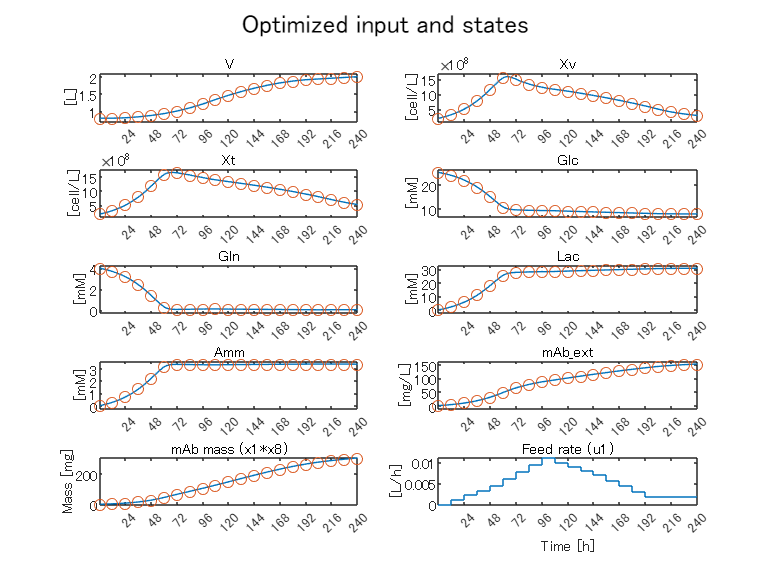

simTrueSFModel(Info_true,Ts,x0);

## Plant-model mismatch disturbs off-line optimization

Specify the model with intentionally errored parameter values to a new nlmpc object.

nlmpcError = nlmpcTrue;
STATEFCN = @deTremblay1992StateFcnError;
nlmpcError.Model.StateFcn = @(x,u) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcError.Optimization.CustomCostFcn = @(X,U,e,data) 1/(X(end,1)*X(end,8) + 0.1) + 0E+2*e^2;
validateFcns(nlmpcError, x0, u0);

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
Optimization.CustomIneqConFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


### Specify the initial guess of the feeding trajectory.

Specify the constant feed rate and the resulting state trajectory to be the initial guess of the optimization.

STATEFCN = @deTremblay1992StateFcnError;
u_const = 1/Tf;
[~,X0_error] = simConstantFeed(Ts,N,STATEFCN,x0,u_const);

Final liquid volume: 1.8 L
Final mAb conc: 48.5948 mg/L
Final mAb amount: 87.4706 mg


options_error = nlmpcmoveopt;
options_error.MV0 = u_const;
options_error.X0 = X0_error(2:end,:);

Start optimization.

timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:51:16

tic
[~,~,Info_error] = nlmpcmove(nlmpcError,x0,u0,[],[],options_error)

カスタムのコスト関数で、スラック変数が使用されていないか、重みが 0 になっています。すべての制約が厳密になります。
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    1.141936e-02     9.763e-03     1.000e+00     0.000e+00     3.521e-02  
    1           3    1.142418e-02     2.234e-04     1.000e+00     2.458e-02     1.292e-02  
    2           5    1.140212e-02     1.764e-06     1.000e+00     4.785e-03     1.846e-03  
    3           8    1.129416e-02     2.118e-07     1.000e+00     2.348e-02     1.728e-03  
    4          11    1.078745e-02     3.628e-05     1.000e+00     1.152e-01     2.067e-03  
    5          16    1.025069e-02     2.154e-04     4.900e-01     1.324e-01     1.998e-03  
    6          19    9.743430e-03     1.456e-04     1.000e+00     1.372e-01     3.386e-03  
    7          21    9.736499e-03     2.853e-06     1.000e+00     3.357e-03     9.398e-04  
    8          24    9.

Info_error = フィールドをもつ struct :
         MVopt: [21×1 double]
          Xopt: [21×8 double]
          Yopt: [21×8 double]
          Topt: [21×1 double]
         Slack: -9.7133e-20
      ExitFlag: 0
    Iterations: 400
          Cost: 0.0087


toc

経過時間は 71.504387 秒です。


printFinalmAb(Info_error);

Final liquid volume: 2 L
Final mAb conc: 57.7319 mg/L
Final mAb amount: 115.464 mg


Simulate the true model with the feeding trajectory optimized in the presense of the plant-model mismatch.

Final liquid volume: 2 L
Final mAb conc: 144.895 mg/L
Final mAb amount: 289.79 mg


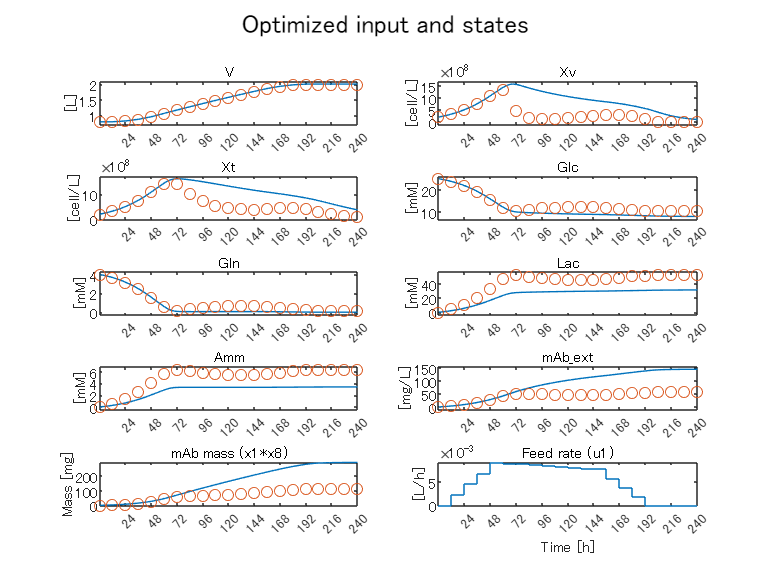

simTrueSFModel(Info_error,Ts,x0);

## On-line reoptimization in the presence of the plant-model mismatch

nlmpcClosedLoop = nlmpcError;
STATEFCN = @deTremblay1992StateFcnError;
nlmpcClosedLoop.Model.StateFcn = @(x,u,N) discretizeStateFcn(x,u,Ts,STATEFCN);
nlmpcClosedLoop.Model.NumberOfParameters = 1;
nlmpcClosedLoop.Model.OutputFcn = @(x,u,N) x;
nlmpcClosedLoop.Optimization.CustomCostFcn = @(X,U,e,data,N) 1/(X(1+N,1)*X(1+N,8) + 0.1) + 0E-6*e^2;
nlmpcClosedLoop.Optimization.CustomIneqConFcn = @(X,U,e,data,N) X(1+N,1) - 2.0;

validateFcns(nlmpcClosedLoop, x0, u0, [], {N});

Model.StateFcn is OK.
Model.OutputFcn is OK.
Optimization.CustomCostFcn is OK.
Optimization.CustomIneqConFcn is OK.
ユーザー指定のモデル、コストおよび制約関数の解析が完了しました。


Open the Simulink model.

mdl = 'MPC_singleFeed';
open_system(mdl)

To use the optional parameter in the prediction model, the model has a Simulink Bus block connected to the `params` input port of the Nonlinear MPC Controller block. To configure this bus block to use the `N` parameter, create a Bus object in the MATLAB workspace, and configure the Bus Creator block to use this object. Name the Bus object `'myBusObject'`.

createParameterBus(nlmpcClosedLoop,[mdl '/Nonlinear MPC'],'myBusObject',{N});

Simulink バス オブジェクト "myBusObject" が MATLAB ワークスペースで作成され、Bus Creator ブロック "MPC_singleFeed/Nonlinear MPC" がこのオブジェクトを使用するように構成されています。


timenow = datestr(datetime('now'));
fprintf('Optimization started at %s',timenow);

Optimization started at 05-Dec-2022 23:52:31

tic
simout = sim(mdl);

カスタムのコスト関数で、スラック変数が使用されていないか、重みが 0 になっています。すべての制約が厳密になります。
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           1    8.653235e-03     2.254e-02     1.000e+00     0.000e+00     2.246e-02  
    1           3    8.733384e-03     2.880e-04     1.000e+00     1.192e-01     7.700e-02  
    2           5    8.728695e-03     1.001e-06     1.000e+00     2.689e-03     8.262e-04  
    3           7    8.722241e-03     9.957e-08     1.000e+00     3.331e-03     7.398e-04  
    4           9    8.702268e-03     1.016e-06     1.000e+00     1.036e-02     5.636e-04  
    5          11    8.698640e-03     4.093e-07     1.000e+00     2.758e-03     5.633e-04  
    6          14    8.680460e-03     2.027e-07     1.000e+00     1.377e-02     5.617e-04  
    7          17    8.674107e-03     6.819e-09     1.000e+00     4.821e-03     1.613e-04  
    8          19    8.

toc

経過時間は 78.590709 秒です。


Final liquid volume: 2 L
Final mAb conc: 154.361 mg/L
Final mAb amount: 308.721 mg


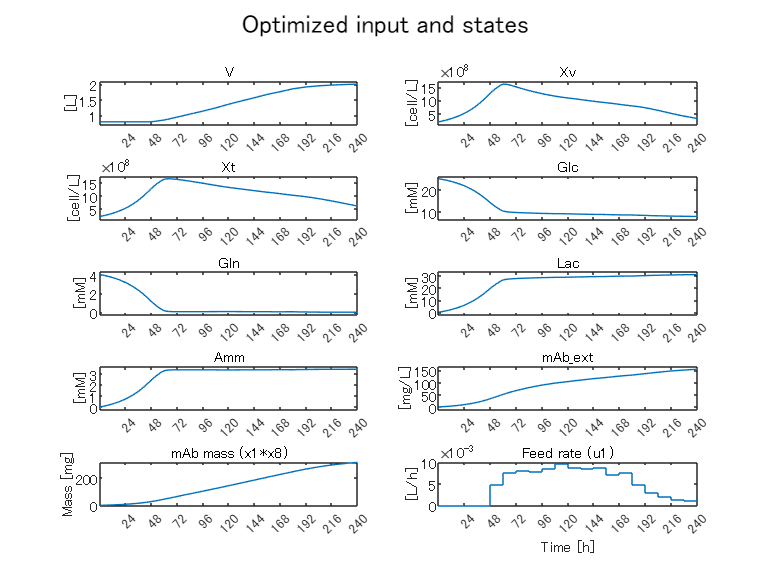

plotSimulinkLog(simout);